## ***EXERCISE:***

## *** Task 01***

### ** Write MATLAB Code for DSB Modulation **

                            𝑦𝐷𝑆𝐵 = 𝐴𝑚 cos(2 𝑓𝑚𝑡) 𝑉𝑐 cos(2 𝑓𝑐𝑡)

 Where 𝐴𝑚 = 1 and 𝑓𝑚 = 100𝐻𝑧, 𝑉𝑐 = 2 and 𝑓𝑐 = 10𝑘𝐻𝑧 

- Plot 𝑚(𝑡), 𝑉c cos (2 𝑓c 𝑡) and 𝑦DSB in time domain for 𝑡 = 0 ∶ 1/fs:1, where 𝑓𝑠 = 1000𝐻𝑧 

- Plot frequency spectrum of m(t), 𝑉𝑐𝑐𝑜𝑠(2 𝑓𝑐𝑡) and 𝑦𝐷𝑆𝐵 in frequency domain and reconstruct demodulated signal using filter. 

- What can you analyze from the frequency components? Are they consistent with your theoretical knowledge? 

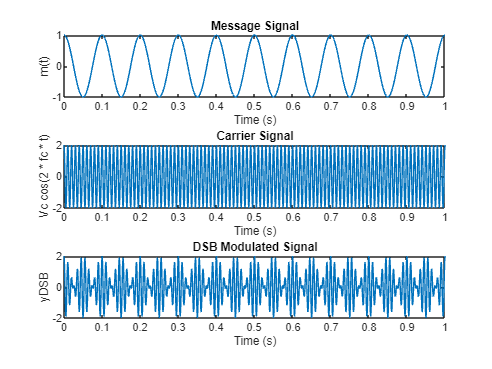

% Parameters
Am = 1;
fm = 10; % in Hz
Vc = 2;
fc = 100; % in Hz
fs = 1000; % in Hz
t = 0:1/fs:1;

% Signals
mt = Am * cos(2 * pi * fm * t);
Vc_cos = Vc * cos(2 * pi * fc * t);
yDSB = Am * cos(2 * pi * fm * t) .* Vc_cos;

% Plot time domain signals
figure;
subplot(3,1,1);
plot(t, mt);
xlabel('Time (s)');
ylabel('m(t)');
title('Message Signal');
subplot(3,1,2);
plot(t, Vc_cos);
xlabel('Time (s)');
ylabel('Vc cos(2 * fc * t)');
%xlim([0 0.2])
title('Carrier Signal');
subplot(3,1,3);
plot(t, yDSB);
xlabel('Time (s)');
ylabel('yDSB');
title('DSB Modulated Signal');

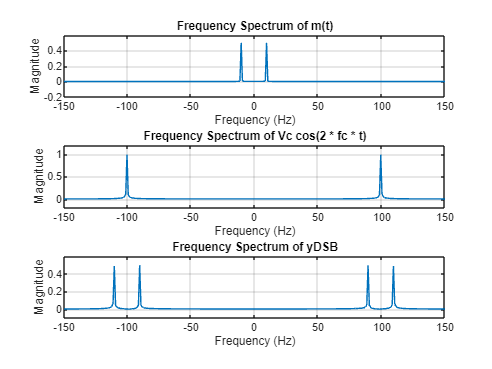

%xlim([0 0.5])

% Plot frequency domain signals
f = -fs/2:fs/length(t):fs/2-fs/length(t);
MT = fftshift(fft(mt));
VC_COS = fftshift(fft(Vc_cos));
YDSB = fftshift(fft(yDSB));
figure;
subplot(3,1,1);
plot(f, abs(MT)/length(t));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of m(t)');
xlim([-150 150])
grid("on")
ylim([-0.2 0.6])

subplot(3,1,2);
plot(f, abs(VC_COS)/length(t));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of Vc cos(2 * fc * t)');
xlim([-150 150])
ylim([-0.2 1.2])
grid("on")


subplot(3,1,3);
plot(f, abs(YDSB)/length(t));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of yDSB');
xlim([-150 150])
ylim([-0.1 0.6])
grid("on")

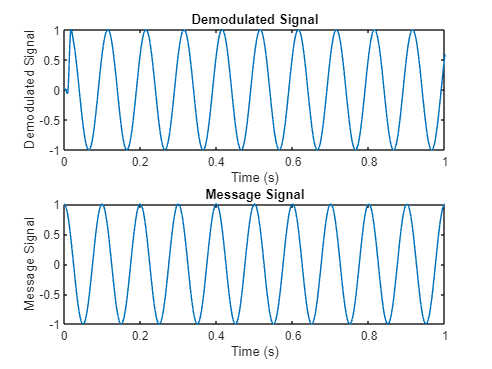




% Reconstruct demodulated signal using filter
y1=yDSB.*Vc_cos;
h = fir1(30,   fc/(fs/2)); % Design a lowpass filter
y_demod =0.5* filter(h, 1, y1); % Demodulate using the filter

% Plot demodulated signal
figure;
subplot(2,1,1)
plot(t, y_demod);
xlabel('Time (s)');
ylabel('Demodulated Signal');
title('Demodulated Signal');
subplot(2,1,2)
plot(t, mt);
xlabel('Time (s)');
ylabel('Message Signal');
title('Message Signal');

## ***Task 02***

### **Implement DSB-SC Modulation and De-modulation using Simulink, you can use the following blocks in Simulink to implement it.**

     Where 𝑓m = 10𝐻𝑧 and 𝑓c = 100𝐻𝑧 

- Signal Generator (Carrier and Message Generation) 

- Dot Product (for multiplication) 

- Analog Filter Design (Butter-low pass) 

- Gain (use at Demodulation side) 

- Scope